# 1.3.04. Решение нелинейных уравнений

**Лекция**

## Построение графиков функций

График функции $y = f(x)$ можно строить с помощью функции `fplot`. Эта функция не требует предварительного вычисления векторов $(x_1,x_2, ...)$ и $(y_1, y_2,...)$. В отличие от `plot` функция `fplot` вычисляет таблицу знчений функции самостоятельно. 

Синтаксис вывода этой фкункции выглядит так:

`    fplot``(f, [limits]),`

где `f` - строка обрабатываемой функции или указатель на функцию, а `limits` - ограничения по аргументу и представляет собой двухкомпонентный вектор: `[xmin xmax].`

Указатель на функцию может быть создан одним из следующих способов:

**    ●**    `f = @function_1` , 

где `function_1` - имя встроенной или созданной пользователем функции (включая хранящиеся в M-файлах). Пример:

f1 = @cos

f1 = function_handle with value:
    @cos


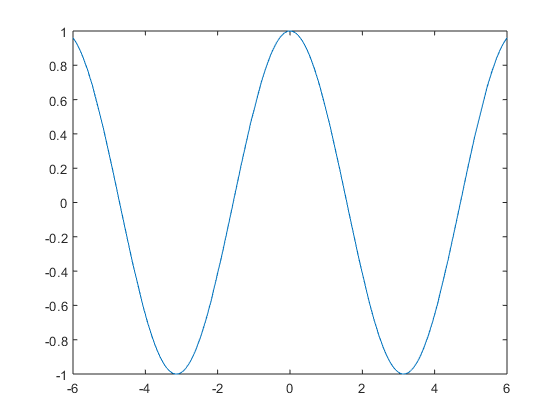

fplot(f1, [-6 6 ])

**    ●**    `f = @(``x``)function_2(``x,P1,P2,P3``)``, `

где `funtion_2` - функция, в которой помимо `x` есть еще 3 аргумента, которым присваиваются постоянные значения `P1,P2` и `P3 `(функцию от 4 аргументов преобразовали в функцию с одним аргументом - `x`). Пример:

Сохранённая в M-файле функция `exp_xyz`:

f2 = @(x)exp_xyz(x,-3,0.5)

f2 = function_handle with value:
    @(x)exp_xyz(x,-3,0.5)


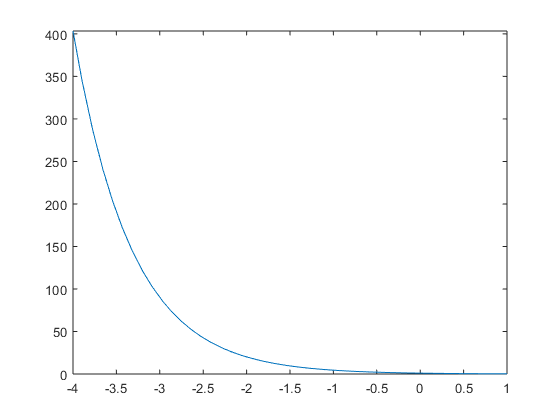

fplot(f2,[-4 1])

**  ●**    `f = @(x)function_formula`**,**

где `function_formula` - текст функции, содержащим формулу с неизвестным x. Пример:

f3 = @(x)sin(x)/(x^2+1)

f3 = function_handle with value:
    @(x)sin(x)/(x^2+1)


fplot(f3,[-20 20])

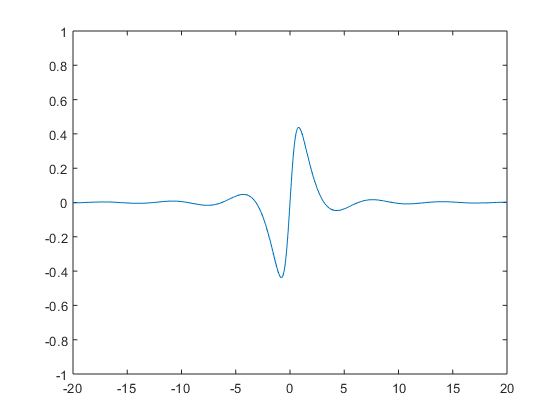

ylim([-1 1 ])

Функция fplot может также строить функции с разрывами обоих родов:

f4 = @(x)(1/x);    % гипербола
f5 = @(x)((abs(x)/x)+1)/2 % cтупенчатая функция Хевисайда

f5 = function_handle with value:
    @(x)((abs(x)/x)+1)/2


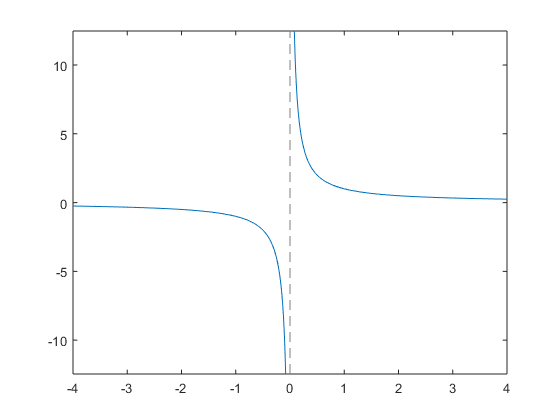

fplot(f4, [-4 4])

fplot(f5)

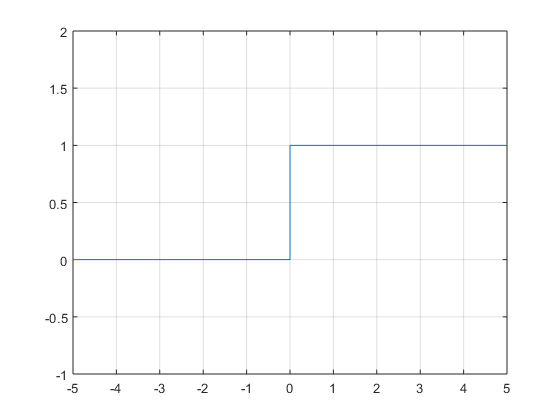

ylim([-1 2])
grid on

## Решение нелинейных уравнений

Из курса математического анализа известно следующее свойство непрерывной функции:

    *Если *$f(a)\cdot f(b)<0$, *то существует точка *$x_0 \in(a,b)$ *такая, что* $f(x_0)=0$. *Это утверждение означает, что график функции *$y = f(x)$ *непрерывный на отрезке *$[a,b]$, *хотя бы в одной точке пересекает ось Ox, если точки *$(a,f(a))$*и *$(b, f(b))$*лежат по разные стороны от оси Ox. *

Для нахождения этой точки $x_0$ в MATLAB есть функция `fzero`. Синтаксис этой функции имеет вид:

    `fzero``(f,[a b])` или `fzero``(f, x1),`

где `f` - функция/ссылка на функцию (как для функции `fplot`), вектор `[a b]` - интервал, на котором требуется найти решение, а `x1` - точка, возле котрой ожидается найти решение. В случае задания точки x1, функция сама пытается определить интервал. 

Функция fzero работает по алгоритму, комбинирующему несколько численных методов нахождения нуля функции: метод половинного деления, метод хорд и метод обратной параболической интерполяции. 

Пример:

Требуется решить уравнение $x = 4(1-\sin(x))$. Cначала его надо преобразовать к виду $\sin(x) - 1 + x /4 =0$, который можно интерпретировать как нули функции $f(x)=\sin(x)-1+x/4$. Задаем функцию и строим график:

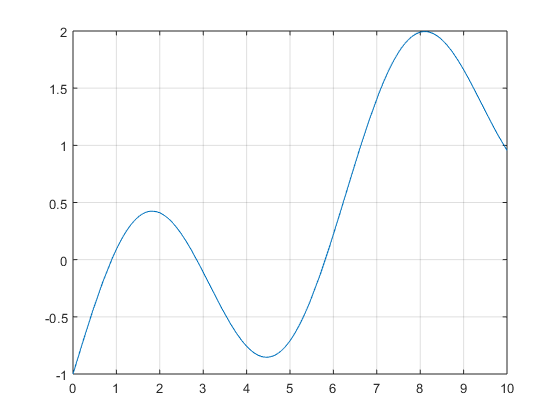

f6 = @(x)sin(x)-1+0.25*x;
fplot(f6,[0,10])
grid on

Из рисунка видно, что корни уравнения лежат в пределах отрезков [0,1], [2,3] и [5,6].

Поэтому:

x_1 = fzero(f6, [0 1])

x_1 = 0.8905

x_2 = fzero(f6, [2 3])

x_2 = 2.8500

x_3 = fzero(f6, 6)  % здесь указана точка, возле которой следует искать корень. Функция найдет ближайший.

x_3 = 5.8128

## Нахождение корней многочленов

Многочлен в MatLab задаётся вектором его коэффициентов, начиная со старшей. Число элементов вектора на один больше степени полинома. Функция `polyval` предназначена для вычисления значений многочлена от некоторого аргумента. Аргумент может быть матрицей или вектором.

Корни многочлена находятся с помощью функции `roots`.

Рассмотрим, к примеру, многочлен $p(x)=x^5+5x^3+7x^2+8x+3$.

Вычислим значение многочлена  в точке $x = -2$ и найдем его корни:

p = [1 0 5 7 8 3];
polyval(p,-2)

ans = -57

roots(p)

ans =    0.7592 + 2.2827i
   0.7592 - 2.2827i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i
  -0.5184 + 0.0000i


Обратная функция к `roots` - `poly` - вычисляет коэффициенты многочлена с заданными корнями: 

%p = [1 0 5 7 8 3];
poly(roots(p))

ans =     1.0000   -0.0000    5.0000    7.0000    8.0000    3.0000


## Решение систем нелинейных уравнений

fsolve из методичек mathworksа